# **Computer Vision (CZ4003) **

# **LAB 2: Advanced image processing **

# **and computer vision technique **

# **Ho Phi Dung - U2020250J**

# **Instructor: Asst Prof. Lu Shijian**

## **Outline:**

This report contains of 4 main parts: 

- Edge detection 

- Line detection

- Stereo vision

- Object recognition (Spatial Pyramid Matching algorithm)

Each part will contain source code (MatLAB/Python), code output, and explanation on the result.

## Part 1: EDGE DETECTION

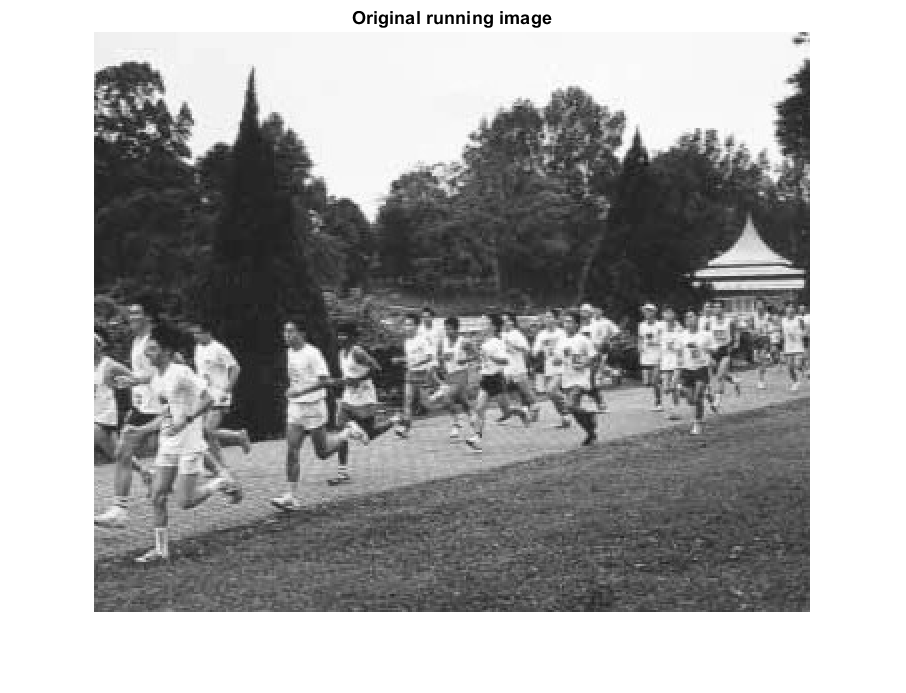

% Part A: Read in image
P = imread('images/maccropped.jpg'); I = rgb2gray(P);
imshow(I, 'InitialMagnification', 200), title("Original running image");

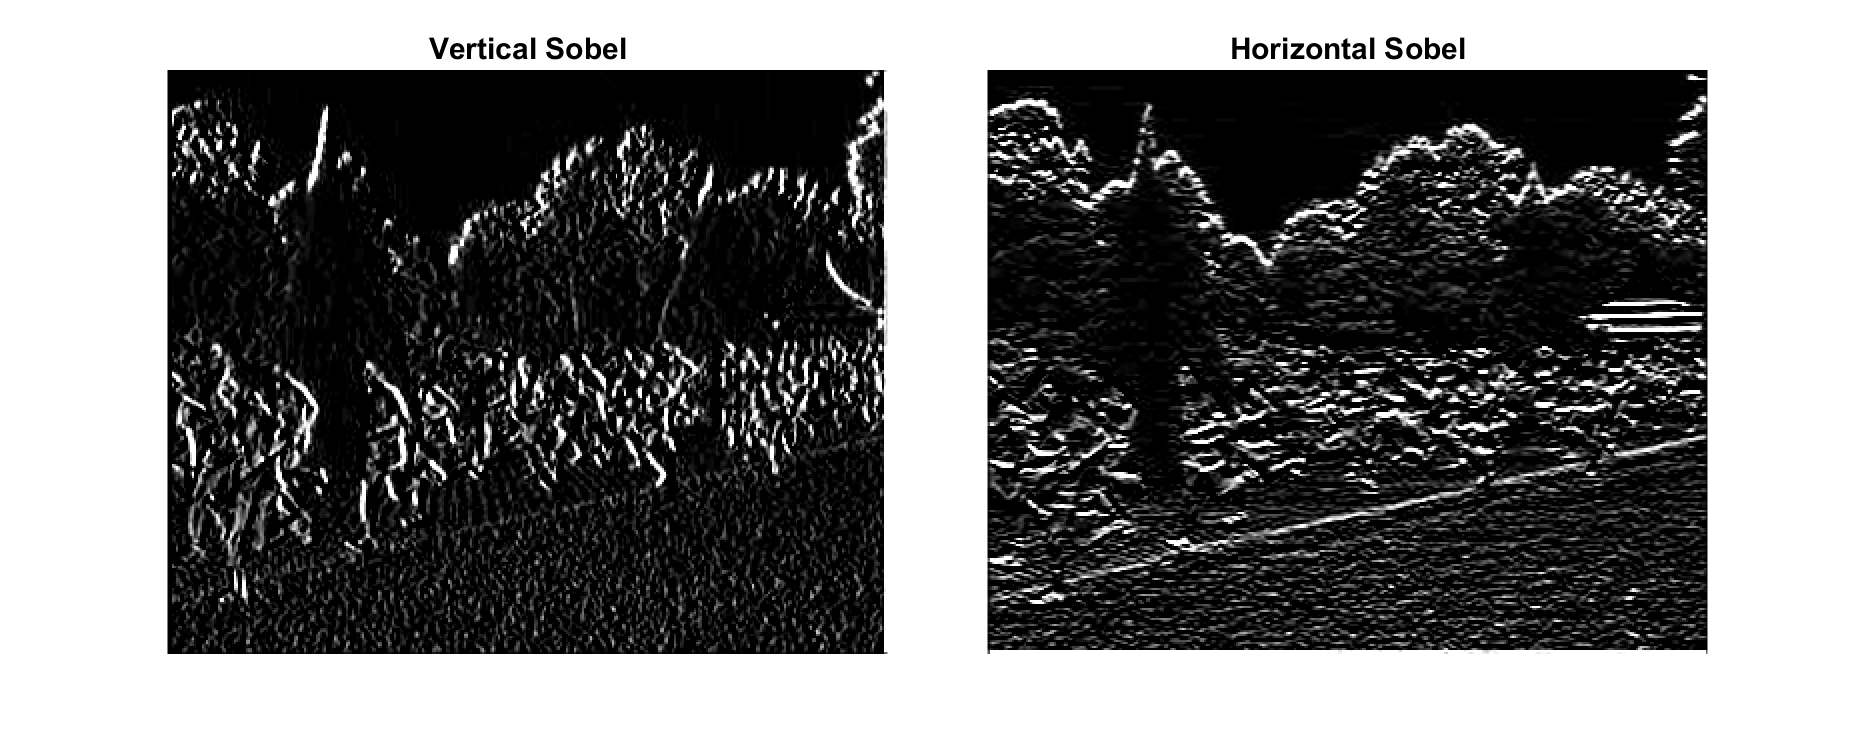

% Part B: Sobel filtering
sobel_v = [ -1 0 1; -2 0 2; -1 0 1; ];
sobel_h = [ -1 -2 -1; 0 0 0; 1 2 1; ];
res_v = conv2(I, sobel_v); res_h = conv2(I, sobel_h);

fig = figure("Name", "Sobel filter");
fig.Position = [100, 100, 1500, 600];
tlo = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact');
imshow(uint8(res_v), 'Parent', nexttile(tlo)), title("Vertical Sobel", 'FontSize', 18);
imshow(uint8(res_h), 'Parent', nexttile(tlo)), title("Horizontal Sobel", 'FontSize', 18);

fig = clf('reset');

Since Sobel kernel is designed to identify gradient along one specific direction (**x** and **y** in this case), region with diagnal gradient will appear with **low intensity, or invisible** in the resultant images. 

For the intuition behind Sobel, it's a simple** gradient **operator $[-{1\over{2}},\ 0,\ {1\over{2}}]$ combined with a shortest non-trivial **Pascal/Gaussian smoothing** $[{1\over{4}},\ {1\over{2}},\ {1\over{4}}]^T$, this however will not be affect if the global scale factor is normalized. Thus the product of 2 operations gives a 3x3 filter. Notice that elements of Sobel filters are **dyadic numbers** so it's efficient when dealing with binary operations (less round-off error, robust to bit shifts, etc).

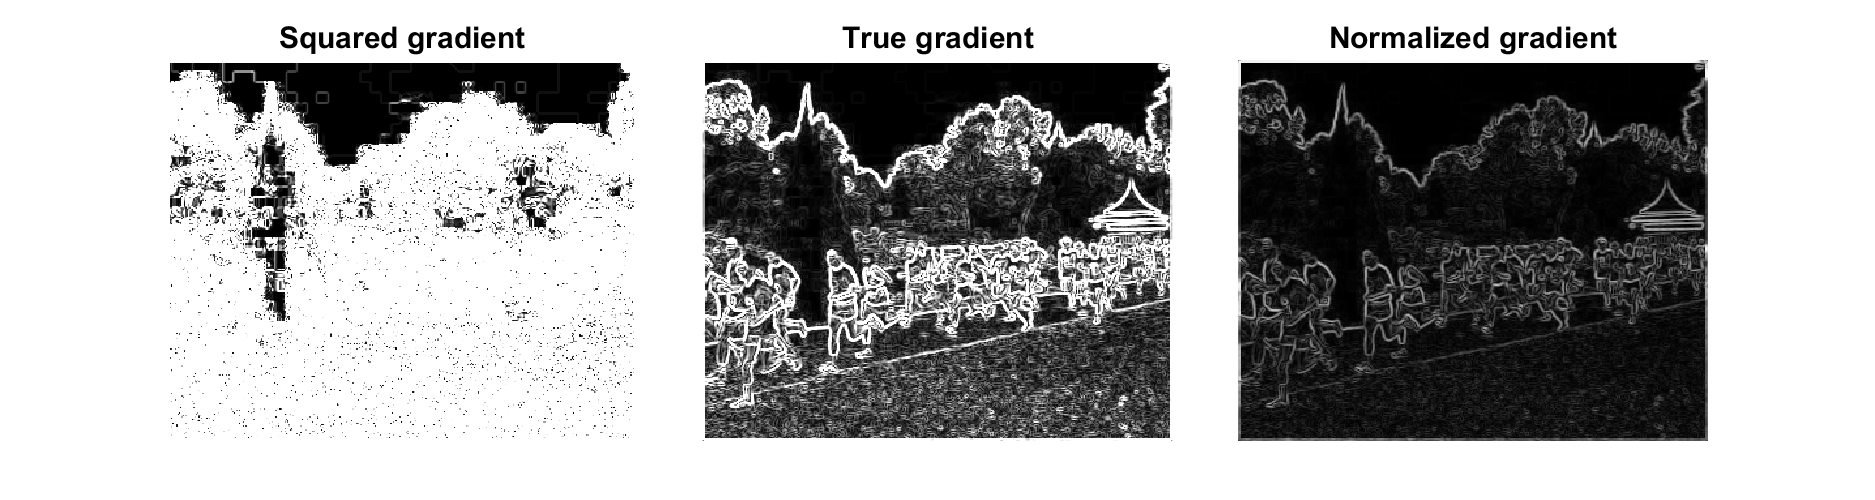

% part C: Get total Gradient
fig.Position = [50 50 1500 400];
tlo = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact');

E = res_v.^2 + res_h.^2; 
imshow(uint8(E), 'Parent', nexttile(tlo)), title("Squared gradient", 'FontSize', 18);
E = sqrt(E); 
imshow(uint8(E), 'Parent', nexttile(tlo)), title("True gradient", 'FontSize', 18);
E = (E - min(E(:))) / (max(E(:)) - min(E(:))) * 255;
imshow(uint8(E), 'Parent', nexttile(tlo)), title("Normalized gradient", 'FontSize', 18);

As stated above, Sobel kernel output magnitude of **images gradient projected onto a specific direction**. Thus, the sum of square is the **squared magnitude of gradient**. However, in the **original **Canny algorithm, square root of E and an orientation map $\Theta = atan({G_y\over{G_x}})$ is used. *Thus I will use the ****magnitude of gradient (e.g: square root of sum square), then normalized the result by a ***`MinMaxScaler() `***(e.g: max value is 255) ****for this experiment. The square root gives much better result and MinMaxScaler is to reduce noisy pattern due to automated clamping by MatLab.*

*As expected, this can display diagonal edges, details and noise level is acceptable.*

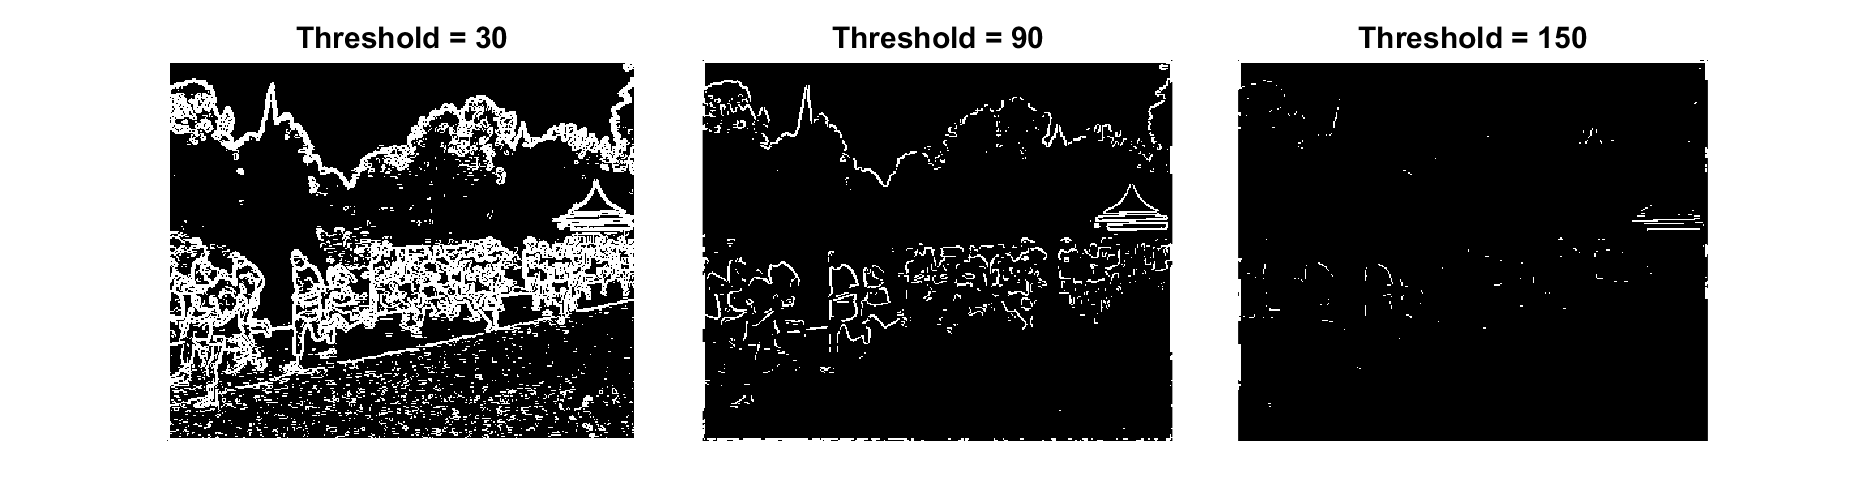

% Part D: Simple thresholding
t = [30, 90, 150];
fig = figure("Name", "Simple Thresholding", "Resize", "off");
fig.Position = [50 50 1500 400];
tlo = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact');
for i = 1:3
    Et = E>t(i);
    imshow(Et, 'Parent', nexttile(tlo));
    title(sprintf("Threshold = %d", t(i)), 'FontSize', 18)
end

As aboved, images are normalized to be in range [0, 255]. Level of thresholding are: **30 = low**, **90 = medium**, **150 = high.** Low level is too noisy while high level filter out most of image details, thus medium thresholding is preferred. Nevertheless, this customized thresholding allow practitioner to extract level of detailedness based on preference or by specific use case. (e.g: set high threshold if want to select sharp edge, low threshold if want to see every possible edge).

However, simple thresholding produces a **binary image**, thus resultant images' quality is very limited (in terms of **brightness integrity**). A side note: systematic thresholding schemes (such as Otsu) might obtain a better (balance) result.

% Part E: Explore MatLAB's Canny edge detection.
tl = 0.04; th = 0.1; sigma = 1.0;

#### (i) Varying Sigma = [1.0, 3.0, 5.0]

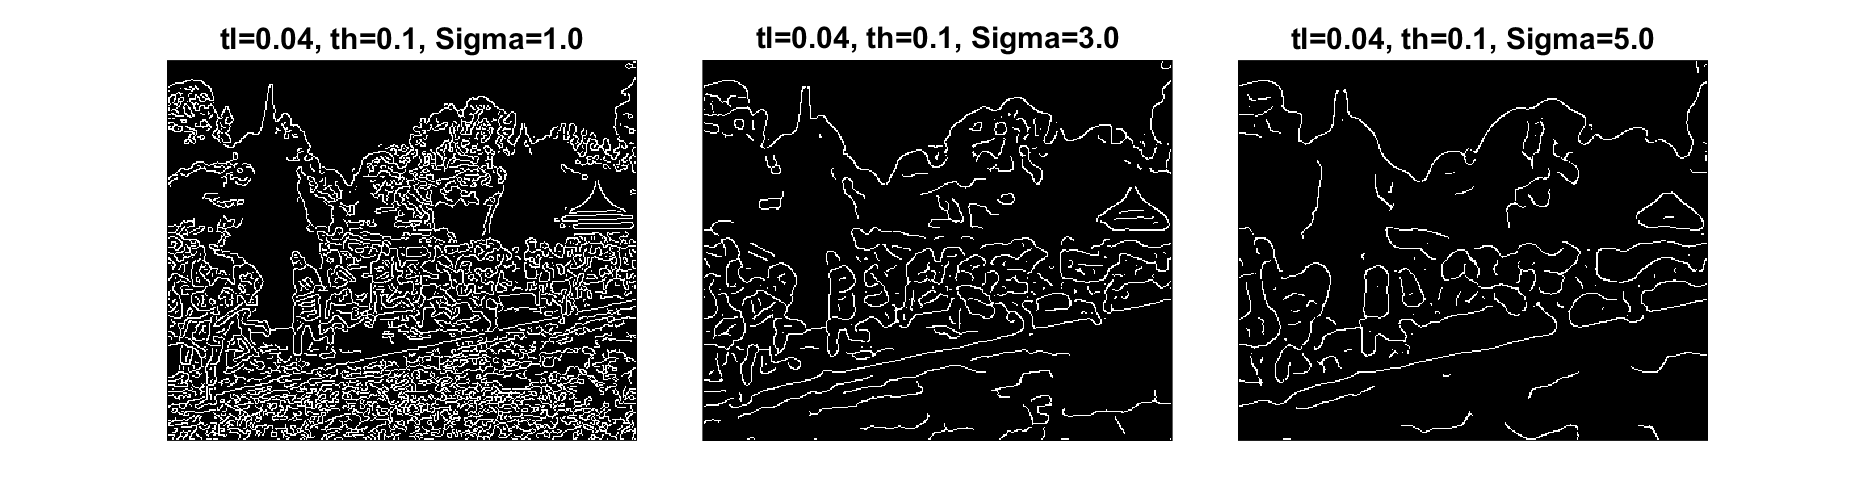

sigmas = [1.0, 3.0, 5.0];
fig = figure("Name", "Varying sigma", "Resize", "off");
fig.Position = [50 50 1500 400];
tlo = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact');
for i = 1:3
    E = edge(I, 'canny', [tl th], sigmas(i));
    imshow(E, 'Parent', nexttile(tlo));
    title(sprintf("tl=0.04, th=0.1, Sigma=%.1f", sigmas(i)), 'FontSize', 18)
end

As can easily be seen from the experiment, **raising sigma filters out more details** in the resultant image. This is due to the nature of **Gaussian filtering, smaller sigma** means steeper filter: $\Psi(x,y)= {1\over{2\pi}}*exp(-{{x^2+y^2}\over{2\sigma^2}})$, **steeper filter** $\rightarrow$**better localization,** but** weaker smoothing** effects. Thus, low sigma value ($\sigma=1$) good at localizing edgels, keeping much of the details while high sigma ($\sigma=5$) is better at removing noisy edges.

#### (ii) Varying low threshold: th = [1.0, 3.0, 5.0]

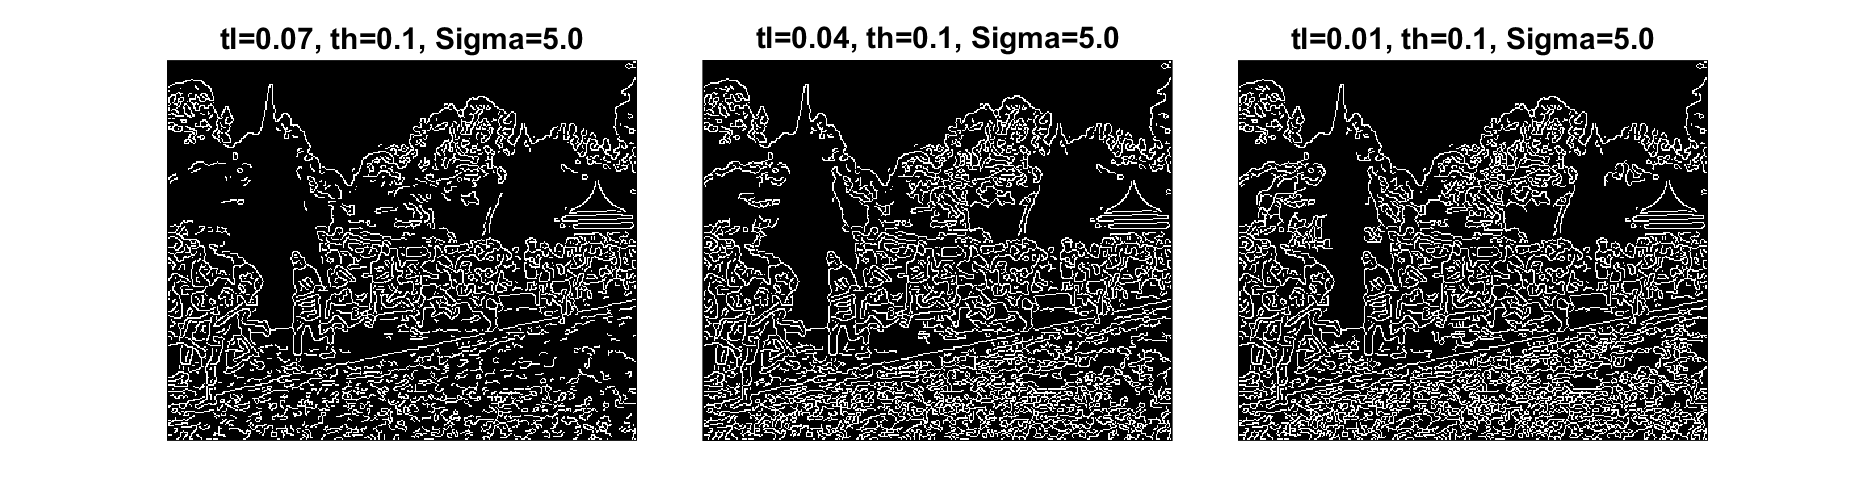

tls = [0.07, 0.04, 0.01];
fig = figure("Name", "Varying low threshold", "Resize", "off");
fig.Position = [50 50 1500 400];
tlo = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact');
for i = 1:3
    E = edge(I, 'canny', [tls(i) th], sigma);
    imshow(E, 'Parent', nexttile(tlo));
    title(sprintf("tl=%.2f, th=0.1, Sigma=5.0", tls(i)), 'FontSize', 18)
end

In Canny Edge detection algorithm,** hysteresis thresholding** is performed by selecting **tl** and **th, **then value above **th **is kept, below **tl** is discarded, between **tl **and **th **is decided to whether be kept or discarded by neighborhood voting (as in Ising model). Therefore, it is intuitively easy to see **lowering tl** will result in **more details** are kept, as we expected from the experiment above.

## Part 2: LINE DETECTION

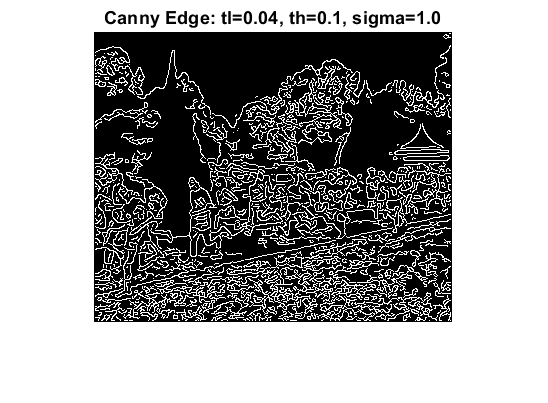

% Part A: Read in -> Canny EDGE.
P = imread('images/maccropped.jpg'); I = rgb2gray(P);
E = edge(I, 'canny', [.04 .1], 1.0);

clf; imshow(E), title("Canny Edge: tl=0.04, th=0.1, sigma=1.0")

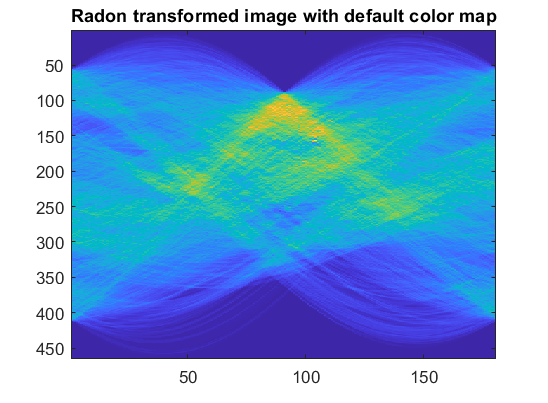

% Part B: Radon transform (Hough binary equivalent)
[R, xp] = radon(E, 0:179);
imagesc(uint8(R)), colormap('default'), title("Radon transformed image with default color map");

Here instead of Hough transform, we use Radon transform, which is a discrete equivalent relation because:

- Recall **Hough transform** and its inverse move back and forth 2 spaces: $(\rho, \ \theta) \leftrightarrow (x,\ y)$ by the relation: $\rho = x \cdot cos(\theta) + y \cdot \sin(\theta)$. That is, a **line in **$(x,\ y)$ corresponding to a** point in **$(\rho,\ \theta)$ while a **wave in **$(\rho,\ \theta)$ is a **point in **$(x,\ y)$. 

- Now the **Radon transform **defined by: 

### 
$$R_{[s,\ \alpha]} = \int_{-\infty}^{\infty} I_{[z \cdot sin(\alpha) + s \cdot cos(\alpha),\ z \cdot cos(\alpha) - s \cdot sin(\alpha)]} \,dz \]$$


Parameters are defined according to the picture below and this can be seen as a projections of 2-D bounded function onto a line.  

- **R: **the resultant Radon transform, $s,\ \alpha,\ z$ are defined as in the figure. 

- **I: **2-D function to be transformed, our image in this case (denoted $f(x, y)$ in the figure).

 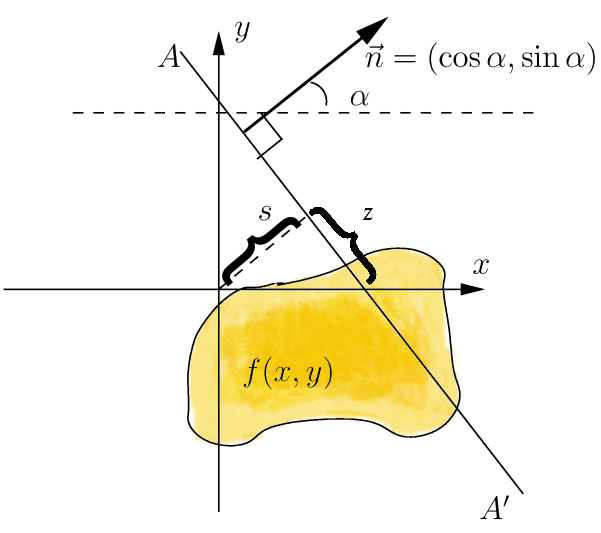

([Image from Wikipedia/Radon_transform](https://en.wikipedia.org/wiki/Radon_transform#/media/File:Radon_transform.png) [2])

In the case of binary image, Radon transformation become **discrete** and thus by **interchanging **$(s,\ \alpha)$** by **$(\rho,\ \theta)$, Radon become Hough transform (e.g: intensity in $(\rho,\ \theta)$is weighted sum of line passing through it in $(x,\ y)$). A line in $(x,\ y)$ can be obtained via inverse transformation defined exactly as Hough transform.

The main different between Radon and Hough transform come from $^{[1]}$:

- **Radon transform:** use a projection integral to **calculate** the characteristic function of a random variable (as the Fourier transform of its probability density function (PDF)) [1] $\longrightarrow$ **mathematically rigorous**, **easily extensible** to higher dimension objects or to complex space (Penrose transform), **well defined for continous function **that satisfy a set of regularity conditions.

- **Hough transform:** obtain the characteristic function by **generating** a random sequence (thus **discrete**), then use emprical histogram binning (or Hough voting) to obtain the PDF.

In conclusion, Hough transform is an **empirical, discretized **version of Radon transform. Though the latter is more mathematically rigorous, **Hough** transform is much** faster in practical settings** (use for low computational capacity devices or high FPS requirement).

% Part C: Pixel with maximum value.
[radius, theta] = find(ismember(R, max(R(:))))

radius = 157

theta = 104

% Part D: Polar to Cartesian 

Conversion from Polar to Cartesian coordinate is performed via: $[x,\ y] = [\rho \cdot cos(\theta),\ \rho \cdot \sin(\theta)]$ (MatLAB's` pol2cart() `function).

theta = 103; % since theta is 0-indexed
radius = xp(157); % x is 1-indexed.
[A, B] = pol2cart(theta*pi/180, radius);
B = -B; % since y-axis is reversed.

To derive C, keep in mind that Radon transformation (or Hough) is done with respect to an origin at the centre of the image, while this origin is at top-left corner in the original image. Thus, A and B (the center) is shifted by $358/2=179,\ 290/2=145$, formula for C is in the code below. 

C = A*(A+179) + B*(B+145)

C = 1.9574e+04

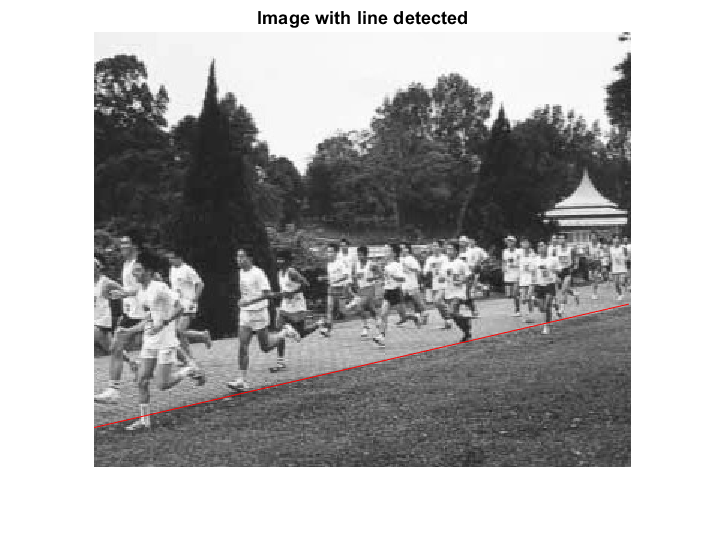

% Part E: Solve for line equation
xl = 0; xr = 357; % image size is 290 x 358.
yl = (C - A * xl) / B;
yr = (C - A * xr) / B;

% part F: Show the image with line
imshow(I, 'InitialMagnification', 150), line([xl xr], [yl yr], 'Color','r'), title("Image with line detected");

The line calculated from our algorithm **almost perfectly match up** with the edge of the running path. In this particular case, edge strength is high, and our algorithm did well in identifying this edge.

Nevertheless, this is not the best achievable result as there are various possible source of errors in calculation steps:

- Since image is** preprocessed by Canny** edge detection algorithm, hyper-parameter selection directly affects overall result. Hence, improvement can be made by **varying hyper parameter** or** directly improve the Canny detector** itself (change smoothing filter [Gaussian filter => adaptive filter], convolution filter [Sobel => Prewitt, Scharr, Cross], all are selected based on image specification).  

- **Non-locality** of peek in Hough **transformed domain**$(\rho,\ \theta)$. This can be improved by **select a set of lines near maxima** (3 to 5 points in transformed domain) and choose the best among them (rank by preference or a designed heuristic function).  

## Part 3: STEREO VISION

% Part A: Define the disparity map 

The source code is provided in "`disp_map.m".`

 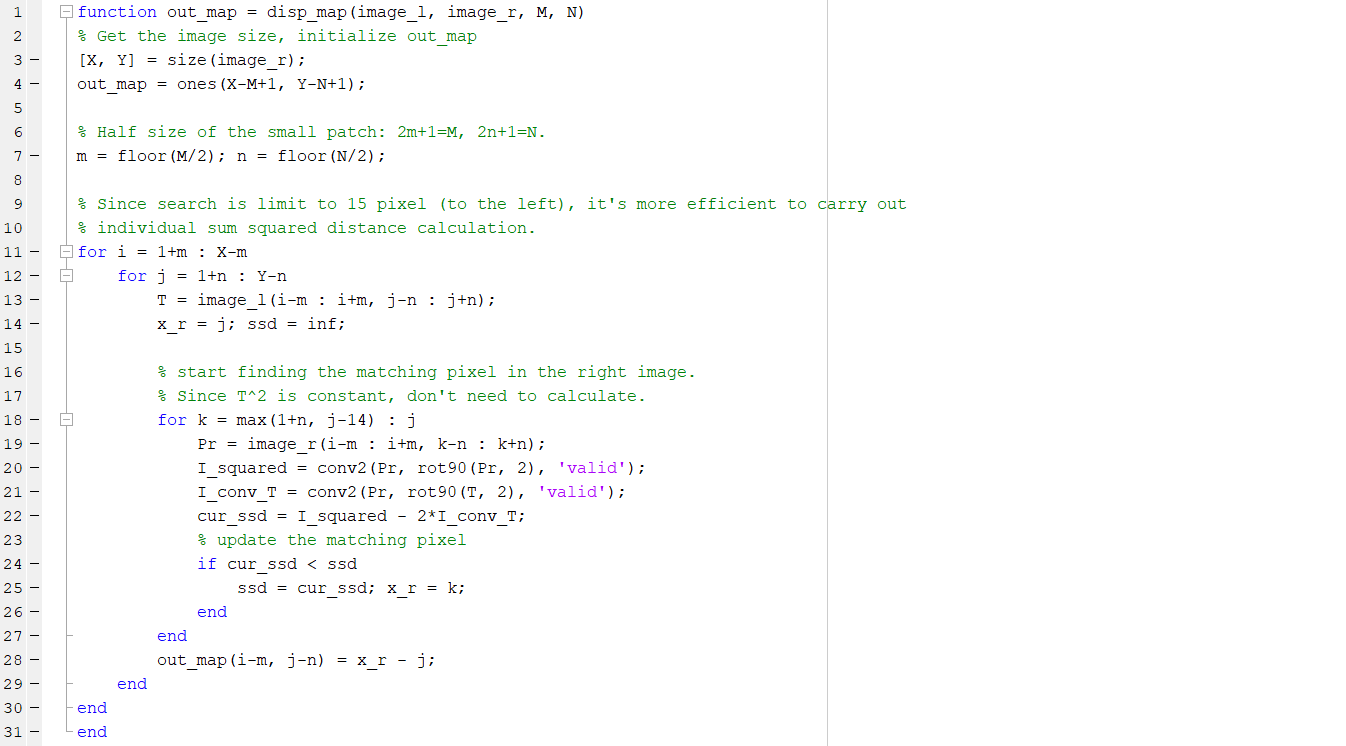

The disparity map algorithm is implemented according to manual specification (source code: disp_map.m). Since the** look up range is restricted** to **15 horizontal pixels** to the right, it's **more efficient** to loop through these **15 pixels** rather **than** calculate a **global SSD image**.

Regarding the implementation details: 

- Use conv2 for parallelized computing of $S(x, y)$.

- Follow lab manual notation, indexing $(i, j)$ here referring to $(Oy,Ox)$ axis orientation of MatLAB image.

% Part B: View Left and Right Image
l = imread('images/corridorl.jpg'); l = rgb2gray(l);
r = imread('images/corridorr.jpg'); r = rgb2gray(r);

fig = figure("Name", "Leftview vs Rightview corridor");
fig.Position = [100, 100, 1500, 600];
tlo = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact');
imshow(l, 'Parent', nexttile(tlo)), title("Left Corridor Image", 'FontSize', 18);
imshow(r, 'Parent', nexttile(tlo)), title("Right Corridor Image", 'FontSize', 18);

The 2 images above are taken from different POV. Though the parralax is quite small, it can be noticed by the first left door or Lena picture.

% part C: Calculating the disparity map
D = disp_map(l, r, 11, 11); disp = imread('images/corridor_disp.jpg');

tlo = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact');
imshow(-D, [-15 15], 'Parent', nexttile(tlo)), title("Calculated corridor disparity map", 'FontSize', 18);
imshow(disp, 'Parent', nexttile(tlo)), title("Corridor reference result", 'FontSize', 18);

Our result is **quite similar** to the reference result. Source of errors might come from:

- Limited look up range (only 15 pixels) when finding the matching pixel.

- Image cut-offs near the edge, noticeably the left edge since matching done from right to left.

- Heavy noise in far field, as suggest by equation: $|\delta Z| = |{Z^2\over{fT}} \cdot \delta d|$.

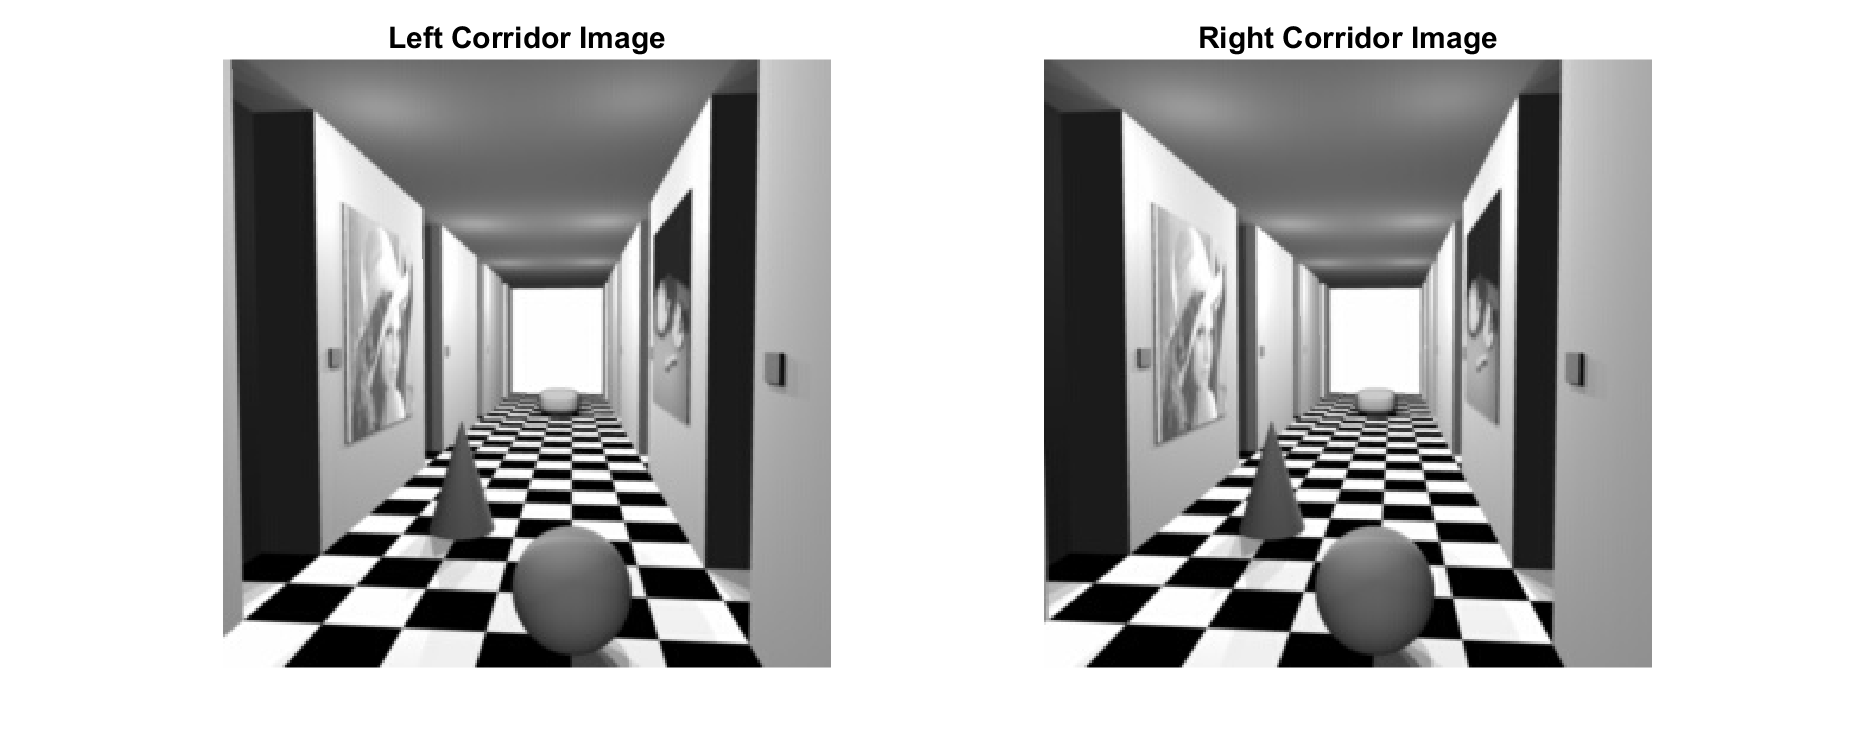

% Part D: Re-run on triclops.jpg
l = imread('images/triclopsi2l.jpg'); l = rgb2gray(l);

r = imread('images/triclopsi2r.jpg'); r = rgb2gray(r);

fig = figure("Name", "Leftview vs Rightview triclops");
fig.Position = [100, 100, 1500, 600];
tlo = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact');
imshow(l, 'Parent', nexttile(tlo)), title("Left Triclops Image", 'FontSize', 18);
imshow(r, 'Parent', nexttile(tlo)), title("Right Triclops Image", 'FontSize', 18);

Same as corridor.jpg, a small POV shift is introduced here. Notice the first window on the left.

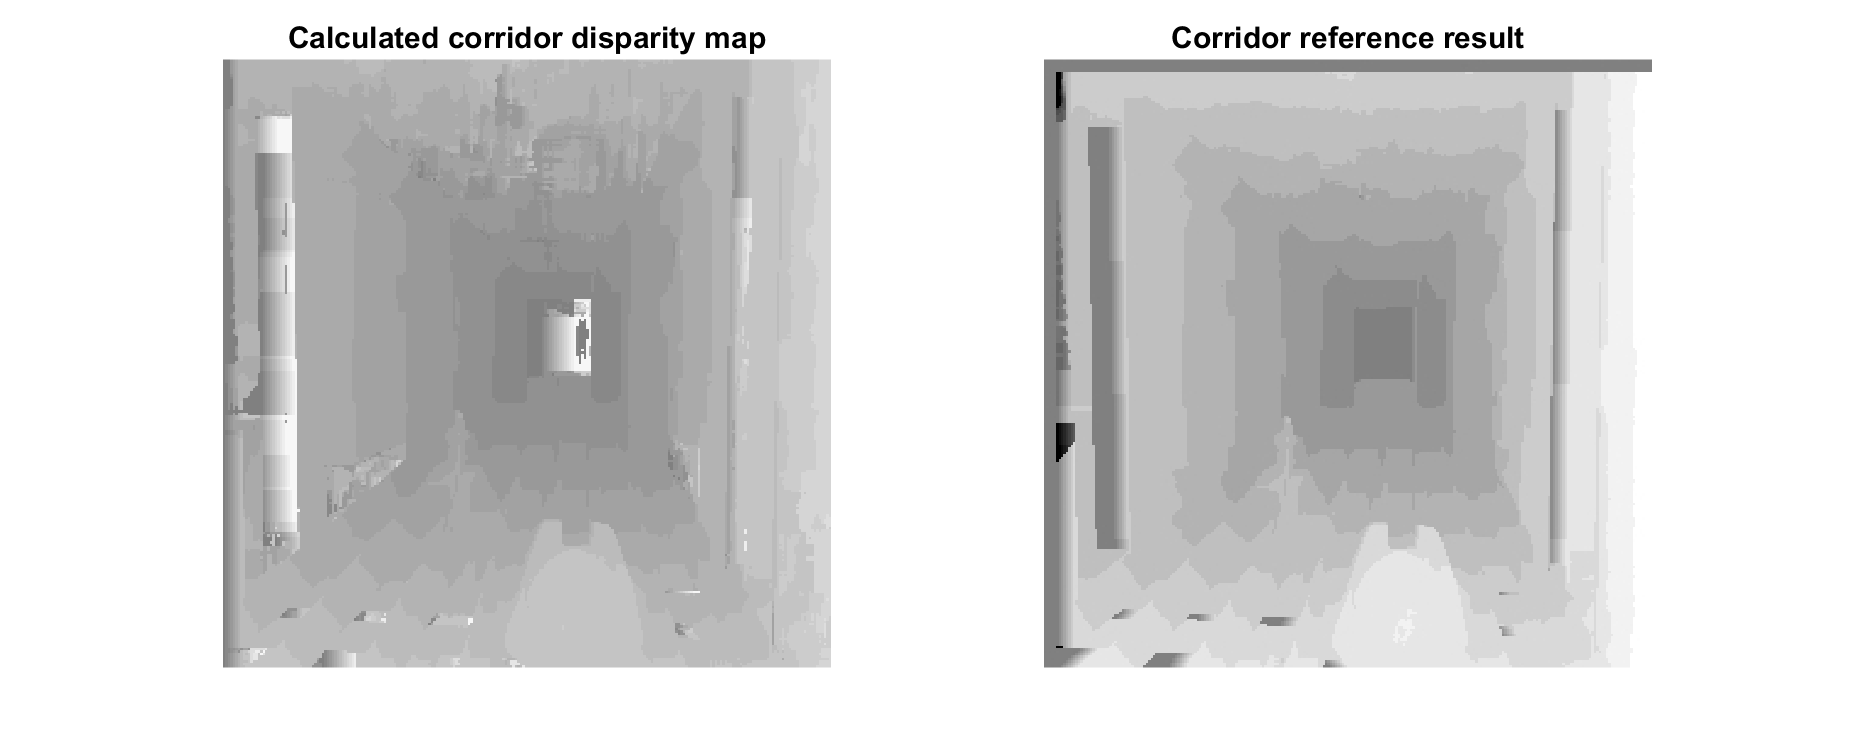

% Calculating the disparity map

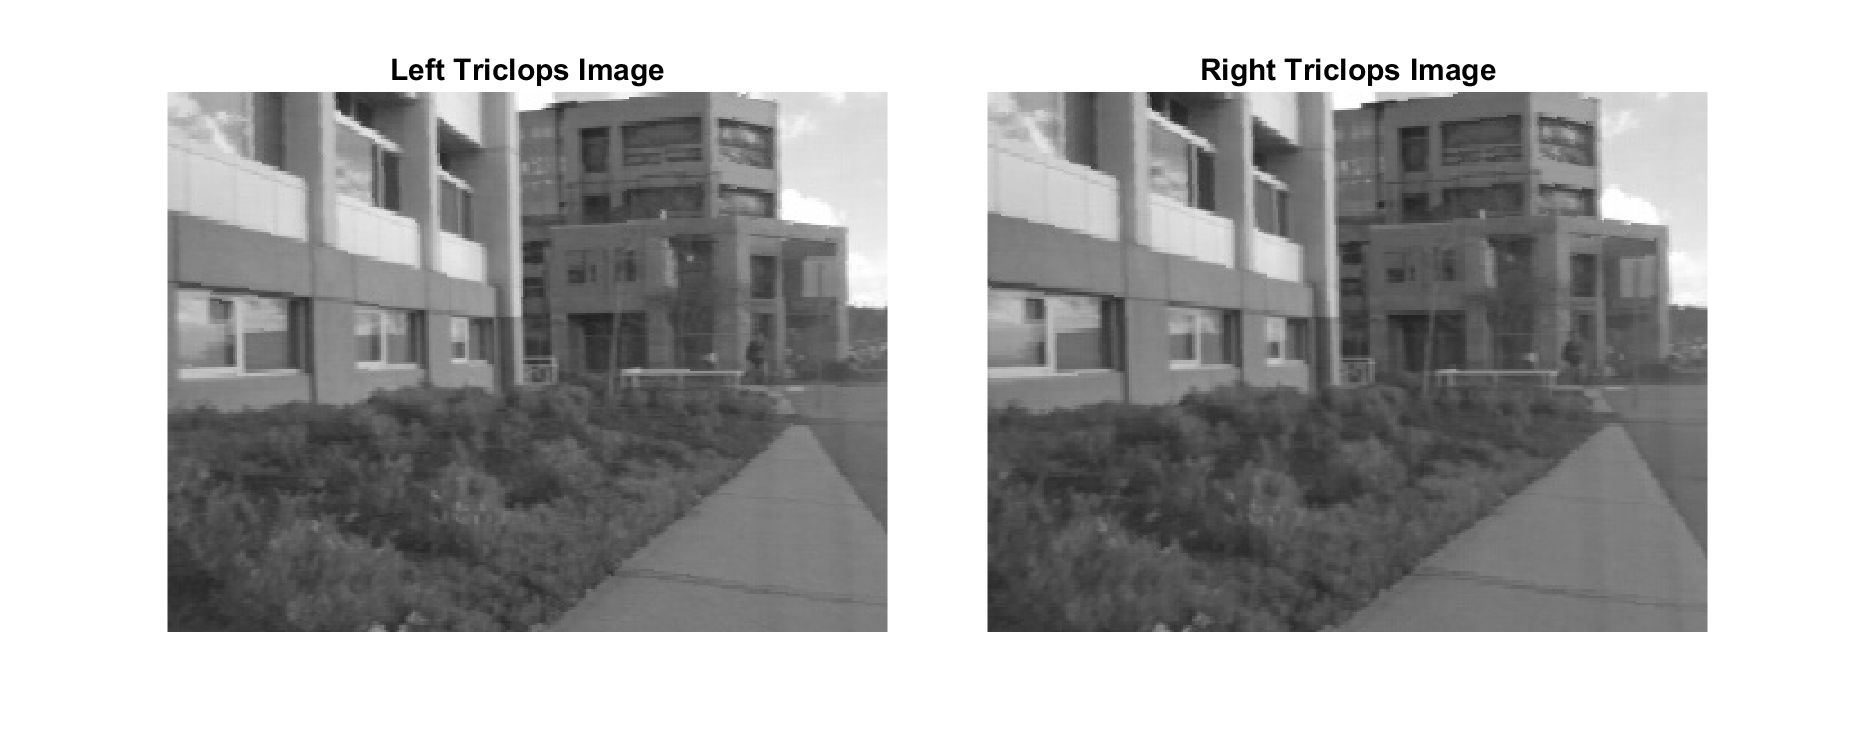

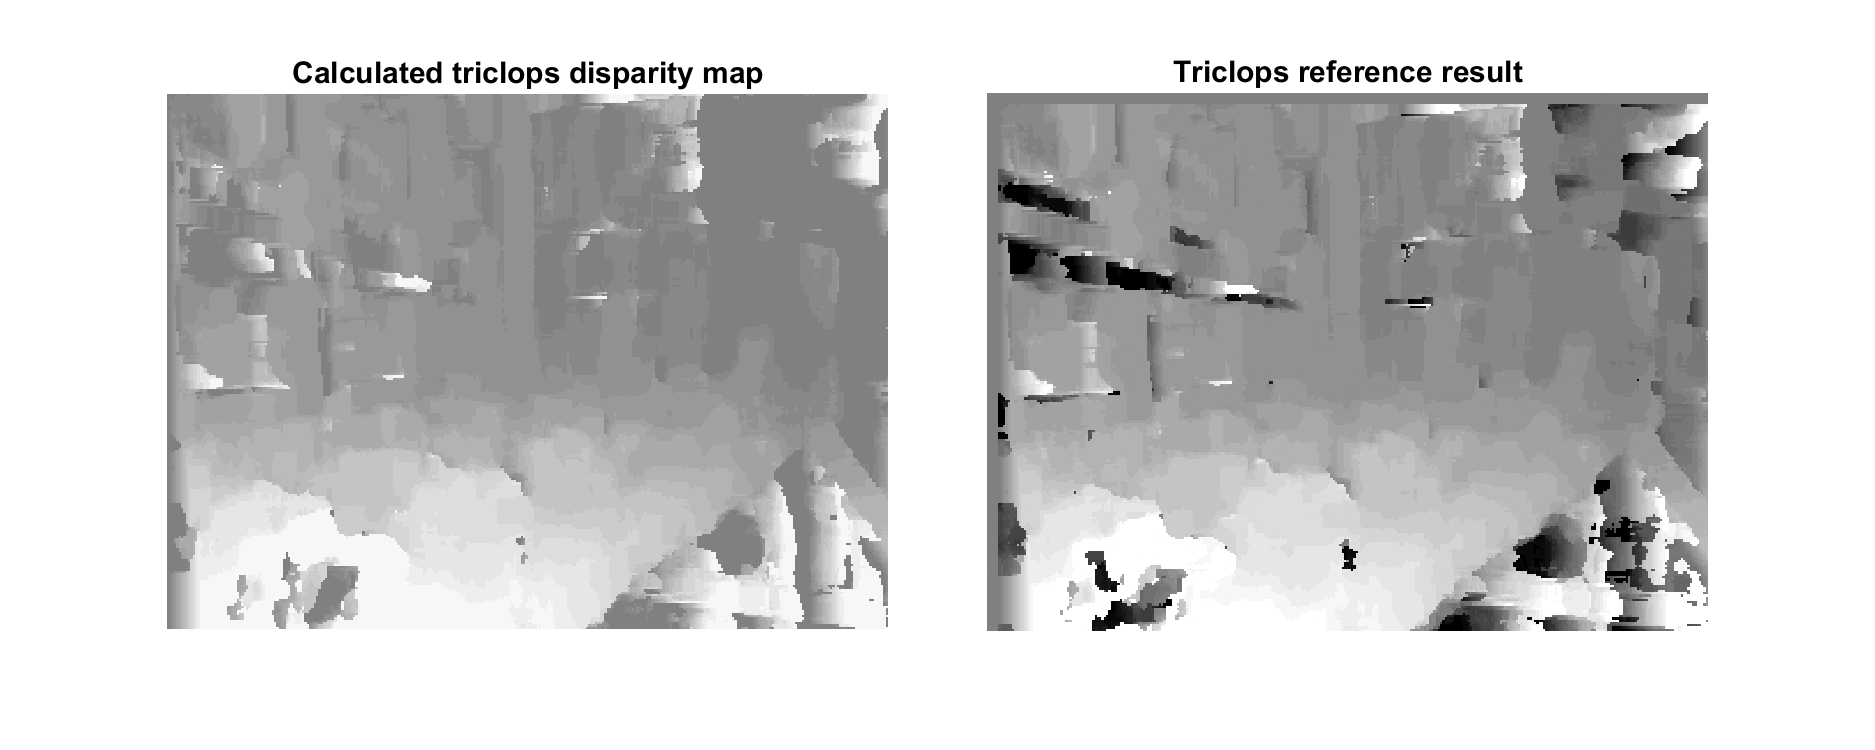

D = disp_map(l, r, 11, 11); disp = imread('images/triclopsid.jpg');

tlo = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact');
imshow(-D, [-15 15], 'Parent', nexttile(tlo)), title("Calculated triclops disparity map", 'FontSize', 18);
imshow(disp, 'Parent', nexttile(tlo)), title("Triclops reference result", 'FontSize', 18);

The calculated disparity map is different from reference result by the same reason as above (corridor.jpg case). However, this image (triclops.jpg) contain more complex details (cluttered objects, noisy background) and thus make the method less robust (though similarity level is still high).

## Part 4: Object recognition (BoW and SPM)

### I. Theory of Spatial Pyramid Matching (SPM):

SPM is an image categorization technique based on **approximating global geometric correspondence. **At a high level, it works by partitioning the image into fine sub-regions by placing a sequence of increasingly coarser grids over the feature space. Then compute the local historgram found inside each subregion, and finally take a weighted sum of the number of matches occurs.

#### A. Pyramid Matching:

Firstly, for each set of feature vectors $(X,Y)$, measure the similarity (or matching index) by using pyramid kernel scheme as discribed above.

**Histogram intersection:**  $(I^l =)\  I(H^{l}_X, H^{l}_Y) = \sum_{i=1}^{D} min(H^{l}_X(i),\ H^{l}_Y(i))$ , where $l = 0,1,..,L-1$ is partition level

**Pyramid Kernel:**                $\kappa^{L}(X,Y) = {I^0 \over {2^L}} + \sum_{l=1}^{L} {I^l \over {2^{L-l+1}}$                       , where $(X,Y)$ are features vector.

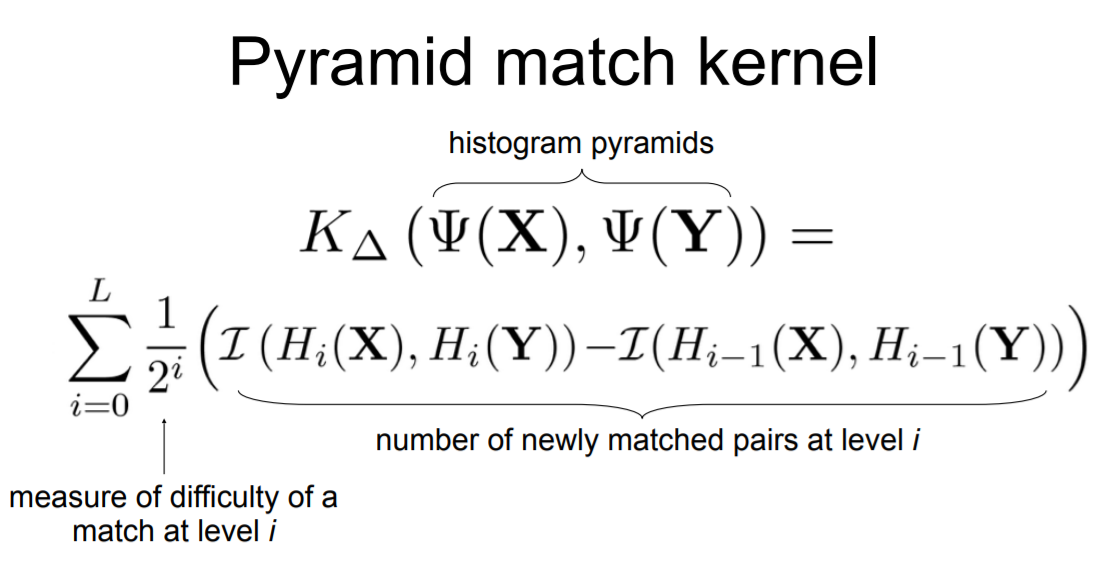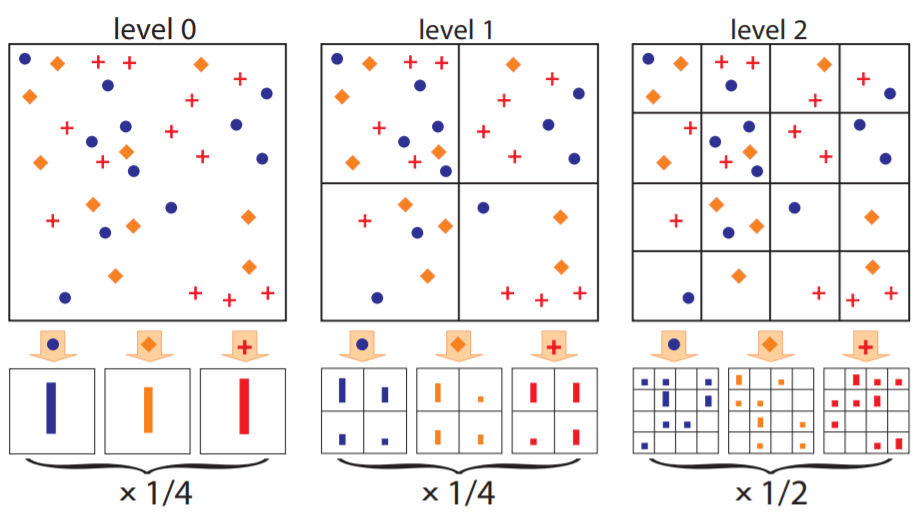

[Image from: [Bag_of_Words](https://pdfs.semanticscholar.org/a50b/31abfe0db1ea81bf3ba59249fab348a0927a.pdf)[4] (left) and [SPM_cs_illiois](http://slazebni.cs.illinois.edu/publications/pyramid_chapter.pdf)[5] (right)]

#### B. Spatial Bag of Words matching scheme:

The authors' ([8]) approach is to use traditional **clustering in features space** to obtains a "Vocabulary" of visual features. In which, features vector are **quantized into** **M discrete types (vocabulary size M), **the total kernel is sum of separate features channel:

#### Total kernel: $K^L(X,Y) = \sum_{m=1}^{M}  \kappa^{L}(X_m,Y_m)$, this is sum over all feature channels.

However, a pyramid matching kernel (as introduced in **Graudman and Darrell [9]**) works with an **orderless** representation of image (e.g: discards all spatial information). To retain spatial information, authors ([8]) perform pyramid matching in the two-dimensional image space (only same features at same level can match), and then weight each spatial histogram according to pyramid matching scheme (e.g: 2 level pyramid has to compute $\sum_{i=0}^{2}4^i = 21$ histogram intersection** separately.**

*A few things to notice:*

- When $L=0$, this reduces to standard "Bag of Words" (BoW) algorithm). Deeper level mean we take spatial information into consideration.

- Since histogram intersection are dimensional independant (after weighted), efficient implementation can **concatenate all pyramid level **into a long vector (which mean this vector represent BoW as well as spatial representation of the image). For a given $(L,M)$, since **each level introduce 4 sub-regions**, resulting vector is $M \cdot \sum_{l=0}^{L} 4^l$ dimensional (e.g: $M=2,L=200 \rightarrow 4200$ dimension). However, these vectors are extremely sparse, thus operations are still efficient.

### II. Implementation  

*Full details are given in the Jupyter notebook (SPM.ipynb), only relevant results are shown here.*

#### 1. Data Loading

As in Svetlana Lazebnik [8] original paper, Caltech101 dataset is being used. The dataset contains pictures of objects belonging to 101 categories (**"GOOGLE_background" is removed** since it is not a single category). About 40 to 800 images per category. Most categories have about 50 images. 

For train test splitting, each class will consist of 30 training images and maximum of 50 for testing (as noted in the paper, following experimental setup of** [9]** and **[10]**). Python code snippet, running instruction, and output are provided in the Jupyter notebook.

#### 2. Building the visual vocabulary (Bag of Words representation)

Visual vocabularies are clustered Scale Invariant Feature Transform (SIFT) descriptors of the entire dataset. In the original paper, 2 types of features are introduced for experimenting. 

- **Weak feature**: Obtained by examining oriented edge points, whose gradient magnitude in a given direction exceed a minimum threshold. Author used 2 scales and 8 orientations $\rightarrow$ $M=16$ features and these can be seen as a global SIFT descriptor of the image. 

- **Strong feature:** Obtained by computing SIFT descriptors of $16 \times 16$ patches over a grid with $8$ pixels spacing. Afterwards, K-means clustering are performed on a subset of random patches (**100 for each image is selected**) to form the set of visual vocabulary. For this experiment, only vocab size of $M=200$ is tested

The process is performed through 2 main steps: 

- Extract SIFT descriptors of entire training data set

- K-means clustering to form a set of visual vocabulary consisting of $M$ elements, or representative features.

*Since the number of subset for random patches for each image (when collecting strong/dense feature) is not specificed in the paper. I tried 2 values of ****100**** and ****256**** for each image (total number of patches for ****image size 300x290**** is about ****1400****), and size of dataset is 30 images for each category. I believe 20% (256/1400) SIFT descriptors from each image is enough to describe the dataset. This maybe the main reason why my result is different from the author. *

#### 3. Compute pyramid kernel representation of the data

As in theory part, histogram of image at each level will be compute then concatenate into a vector, which contains representation of image in spatial domain as well as in visual vocabulary. Following the paper, 2 modes of pyramid are being computed:

- Single level: calculation happen at only 1 specific level $L$

- Total pyramid: weighted sum of all levels until $L$

### III. Training and result

Training and set up follow author settings. A few things to keep in mind:

- In the paper, authors perform training on **15 different shuffles** of the dataset. However, **since each run is very long** (single run take more than 3 hours to prepare data for training), I only do on** 1 pass** with the assumption that ``sklearn.utils.shuffle`` perform in an unbiased manner.

- All **hyper-parameters** for Linear SVM Classifier have been **selected through trial and error **(manual/grid search). Though much effort is made, it is not guaranteed the best has been found.

- Training and testing histogram (in form of Bag of Words or visual vocab representation) will be **normalized **by a ``sklearn.preprocessing.MaxAbsScaler`. `This is to avoid **vanishing gradient** and **floating-point error** due to very small original value (about $10^{-3} - 10^{-4}$), this scaler **scale maximum value to 1** and **preserve sparsity** of original data. 

- For **strong features, **I test on 2 sizes of subset of patches for each image, namely: **100** and **256** (corresponding to **7%** and **20%** information of original dense SIFTs)

- For **weak features**, I'm not sure how exactly they are extracted from the paper. To quotes: *"we have so called “weak features,” which are oriented edge points, i.e., points whose gradient magnitude in a given direction exceeds a minimum threshold. We extract edge points at two scales and eight orientations, for a total of M = 16 channels." (Section 4, pg. 3). *My interpretation is to calculate SIFT descriptors with 16 keypoints from each image, patch size is still $16x16$. The keypoints are placed at 8 edges at 2 scales of the image as follow:

     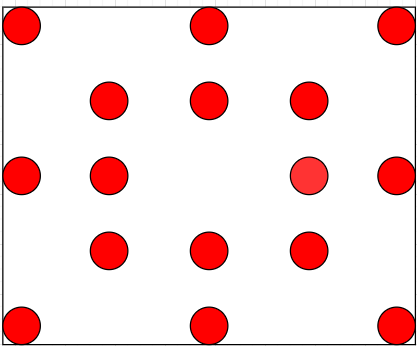

*(Red circles depict keypoints to calculate SIFT)*

Here is the reference training result vs. my result (more training, inferencing details refer to Jupyter notebook):

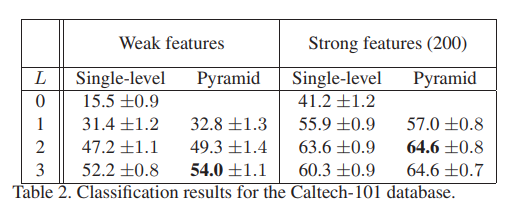    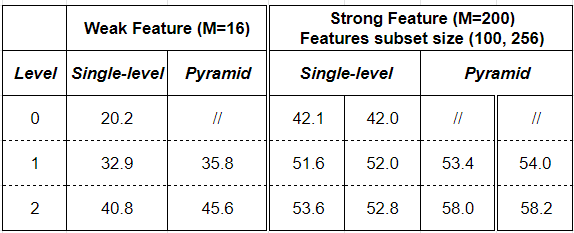

*(Reference result [8])*                                                              *(My Result)*

### IV. Conclusion

In my attempt of replicating *S. Lazebnik [8] *Spatial Pyramid Matching algorithm on Caltech101 dataset, lots of implementation specs from original paper have been taken into details. However, the result still differs because of following possible reason:

- **Pyramid Kernel:** *(Dense/Strong feature)* number of features subset selected from each image is not specified in the paper || *(Weak/Sparse features) *might different from the author as they are might own interpretation from the paper

- **Data splitting:** though number of train test split possibly matches, their splitting scheme may differ since I only do 1 pass.

- **SVM and K-means classifiers**: Hyper-parameters of classifier are not fully specified, the implementation from `sklearn` might also be different.

Nevertheless, main result of SPM algorithm is still presented. Its improvement comparing to traditional BoW and higher accuracy of all pyramid level vs. single-level is shown in the result table (above).

*A few notes on possible improvements, full details refer to the Jupyter notebook:*

- Efficient data stream has not yet been implemented.

- Parallelization can be implemented in various steps.

- Larger size of features subset from each image could be selected to capture more details (increase to 525 or even 900).

## Reference: 

- [Stack Exchange discussion: /a/472](https://dsp.stackexchange.com/a/472)

- [Wikipedia/Radon_trasnform](https://en.wikipedia.org/wiki/Radon_transform)

- [Wikipedia/Hough_transform](https://en.wikipedia.org/wiki/Hough_transform)

- [Bag_of_words](https://pdfs.semanticscholar.org/a50b/31abfe0db1ea81bf3ba59249fab348a0927a.pdf)

- [SPM_cs_illiois](http://slazebni.cs.illinois.edu/publications/pyramid_chapter.pdf)

- [OpenCV API](https://docs.opencv.org/master/) 

- [SIFT_Introduction](https://www.diva-portal.org/smash/get/diva2:480321/FULLTEXT02)

- [S. Lazebnik, C. Schmid and J. Ponce, "Beyond Bags of Features: Spatial Pyramid Matching for Recognizing Natural Scene Categories," 2006 IEEE Computer Society Conference on Computer Vision and Pattern Recognition (CVPR'06), 2006, pp. 2169-2178, doi: 10.1109/CVPR.2006.68.](https://inc.ucsd.edu/mplab/users/marni/Igert/Lazebnik_06.pdf)

- [K. Grauman and T. Darrell. Pyramid match kernels: Discriminative classification with sets of image features. In Proc. ICCV, 2005.](https://www.cs.utexas.edu/~grauman/papers/grauman_darrell_iccv2005.pdf)

- [J. Zhang, M. Marszalek, S. Lazebnik, and C. Schmid. Local features and kernels for classifcation of texture and object categories: An in-depth study. Technical Report RR-5737, INRIA Rhone-Alpes, 2005.](https://hal.inria.fr/inria-00070281/document)